# Accuracy and precision of linear systems

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIOVASCULAR AND RESPIRATORY MONITORING DEVICES

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter1/SensorModel'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

In this notebook, we will introduce two sensors models. They include:

- The linear model that is used for generating data and comparing the output of paired measurements. The measurements are done with a sensor that has no bias and has small random error agains anouther sensor with a bias, scaling factor not equal 1 and larger measurement noise. The model is used to determine the **errors in measurements **and for** evaluating the agreement**.

- The sensor model in Simulink that includes linear function as well as the gain, saturation block, bandlimiter and so on. This model allows for simulating different types of sensors.

- The sensor model in Simulink that includes 3rd order polonomial nonlinear function as well as the gain, saturation block, bandlimiter and so on. This model allows for obtaining **linearity error**.

## Linear model in Matlab

### Evaluating error

In this example, we consider measurement where the "true" value of measurement is 1. The measurement is repeated N times. It is performed using 2 methods: 1 and 2. The measurement errors are modeled as random numbers coming from Normal distribution. Also, there could be some internal variability in x that is also modeled using the standard deviation sigma_x. If the variable Input_variance=0, then this internal variability is not taken into account.

Several combinations are considered:

- Concordance coefficient slide

Input_variance=1;

sigma_e1=0.01;

sigma_e2=0.1;

beta0=0;%0.01

beta1=1.5;%1.01;

sigma_x=0.2;

mu_x=1;

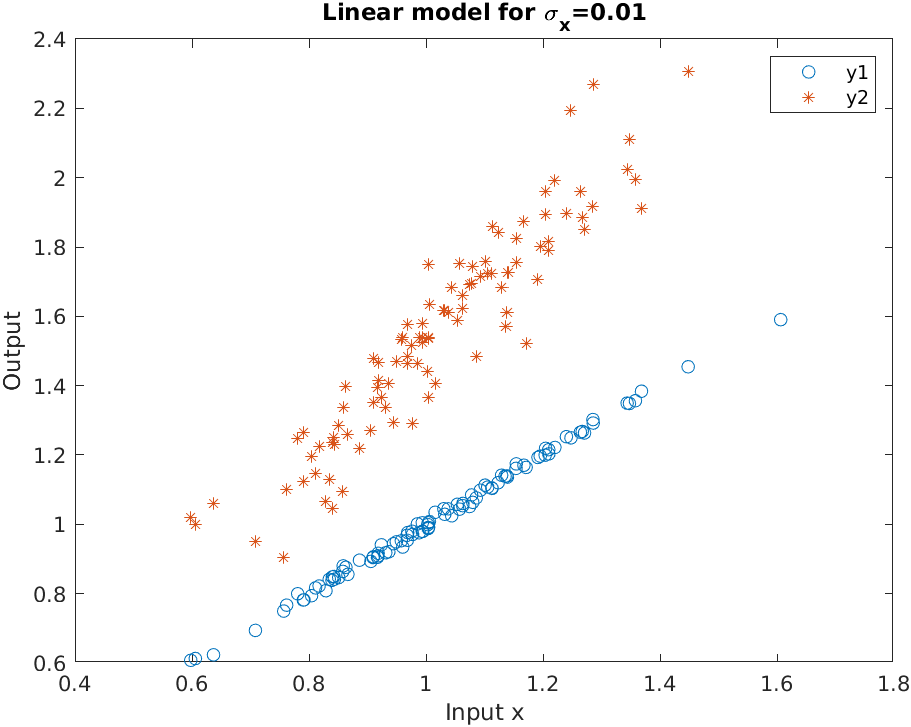

        2. Bland Altman and scatter-plot slides - no biases

N=100;

sigma_e1=0.01;

sigma_e2=0.03;

beta0=0;%0.01

beta1=1;%1.01;

if Input_variance==0 

    sigma_x=0;

else

    sigma_x=0.2;

end

mu_x=1;

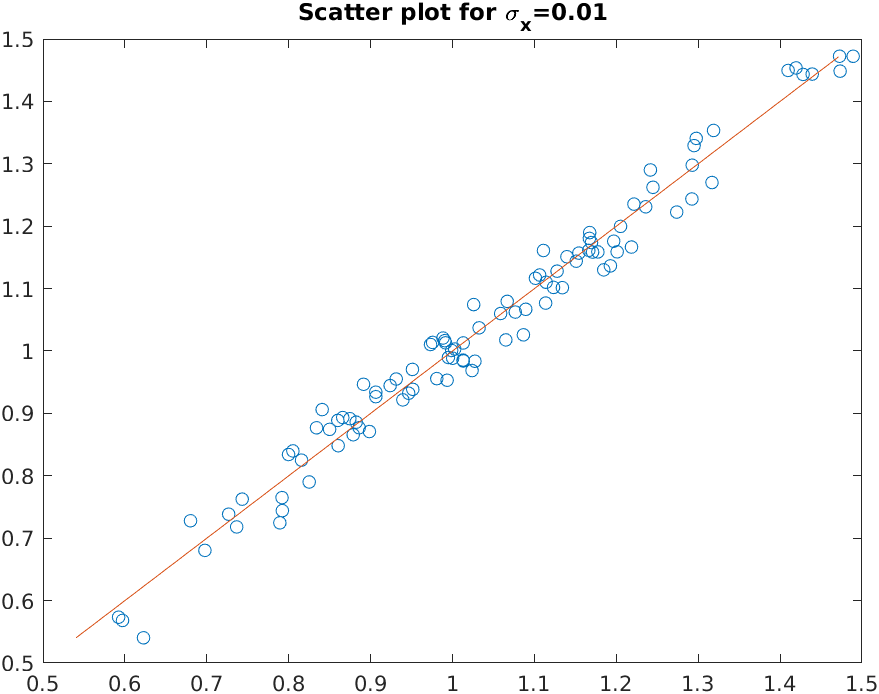

        3. Bland Altman and scatter-plot slides - with biases

N=100;

sigma_e1=0.01;

sigma_e2=0.03;

beta0=0.02;%0.01

beta1=1.01;%1.01;

if Input_variance==0 

    sigma_x=0;

else

    sigma_x=0.2;

end

Input_variance=0; %or 1

N=100;
sigma_e1=0.001;
sigma_e2=0.01;
beta0=0.01; %0
beta1=1;%1.01; %1
if Input_variance==0 
    sigma_x=0;
else
    sigma_x=0.2;
end
mu_x=1;

x=mu_x+sigma_x*randn(N,1);
e1=sigma_e1*randn(N,1);
e2=sigma_e2*randn(N,1);

y1=x+e1;
y2=beta0+beta1*x+e2;

D=y2-y1;

CCC = f_CCC([y1 y2],0.05);
Ch1 = ['Pearson coeff is: ',num2str(CCC{1, 1}.pearsonCorrCoeff)];
disp(Ch1)

Pearson coeff is: -0.12897


Ch2 = ['Concordance correlation coeff is: ',num2str(CCC{1, 1}.est)];
disp(Ch2)

Concordance correlation coeff is: -0.013396


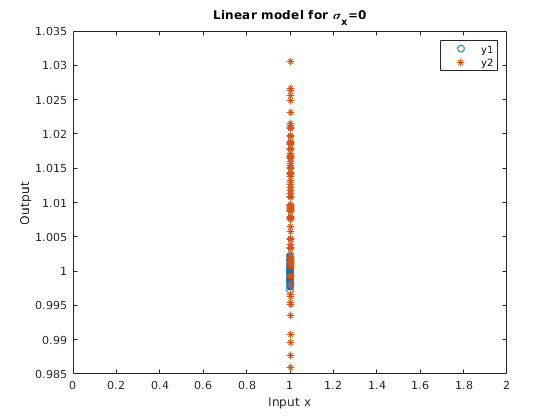


figure
plot(x,y1,'o')
hold on, plot(x,y2,'*')
xlabel('Input x')
ylabel('Output')
if Input_variance==0 
    title('Linear model for \sigma_x=0')
else
    Ch3 = ['Linear model for \sigma_x=',num2str(sigma_x)];
    title(Ch3)
end
legend('y1','y2')

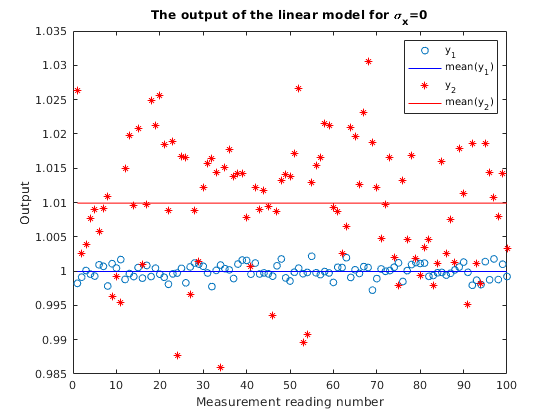

figure
plot(y1,'o')
hold on, 
plot([1 length(y1)],[mean(y1) mean(y1)],'b')
plot(y2,'*r')
plot([1 length(y2)],[mean(y2) mean(y2)] ,'r')
xlabel('Measurement reading number')
ylabel('Output')
if Input_variance==0 
    title('The output of the linear model for \sigma_x=0')
else
    Ch3 = ['The output of the linear model for \sigma_x=',num2str(sigma_x)];
    title(Ch3)
end
legend('y_1','mean(y_1)', 'y_2', 'mean(y_2)')

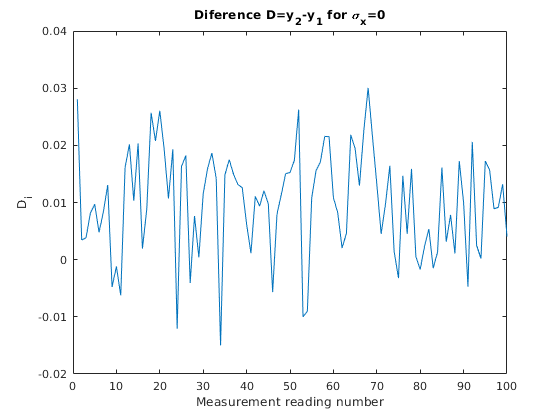

annonation_save('',"Fig1.5.jpg", SAVE_FLAG);

figure
plot(D)
xlabel('Measurement reading number')
ylabel('D_i')
if Input_variance==0 
    title('Diference D=y_2-y_1 for \sigma_x=0')
else    
    Ch3 = ['Diference D=y_2-y_1 for  \sigma_x=',num2str(sigma_x)];
    title(Ch3)
end

### Evaluating agreement

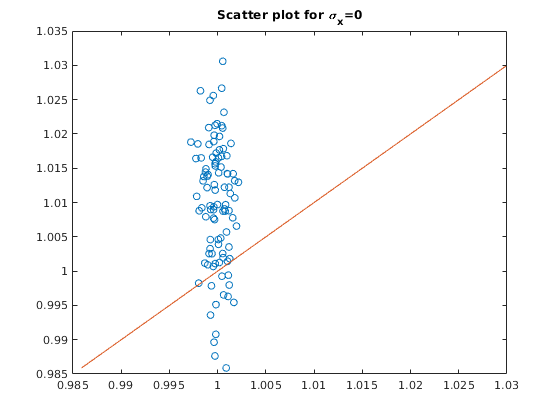

% Scatter plot
x2 = min(y2):0.001:max(y2);
figure
plot(y1,y2,'o')
hold on
plot(x2,x2)
if Input_variance==0 
    title('Scatter plot for \sigma_x=0')
else
    Ch3 = ['Scatter plot for \sigma_x=',num2str(sigma_x)];
    title(Ch3)   
    title('Scatter plot for \sigma_x=0.01')  
end

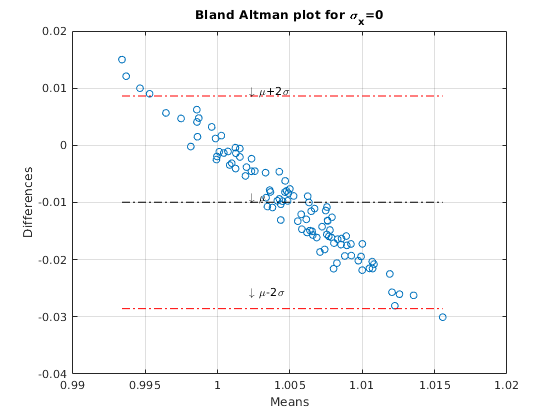

% Bland Altman plot
method1=y1';
method2=y2';
meanArray = mean([method1;method2]);
diffArray = method1-method2;
meanOfDiffs = mean(diffArray);
stdOfDiffs = std(diffArray);
confRange = [meanOfDiffs + 2.0 * stdOfDiffs, meanOfDiffs - 2.0 * stdOfDiffs];
figure
plot(meanArray,diffArray,'o'); 
hold on;
line([min(meanArray) max(meanArray)],[confRange(1) confRange(1)],'Color','red','LineStyle','-.');
line([min(meanArray) max(meanArray)],[confRange(2) confRange(2)],'Color','red','LineStyle','-.');
line([min(meanArray) max(meanArray)],[meanOfDiffs meanOfDiffs],'Color','black','LineStyle','-.');
grid; ylabel('Differences'); xlabel('Means');
text(max(method1),1.1*confRange(1),{'\downarrow \mu+2\sigma'})
text(max(method1),0.9*meanOfDiffs,{'\downarrow \mu'})
text(max(method1),0.9*confRange(2),{'\downarrow \mu-2\sigma'})
%xlim([0.97 1.03])
if Input_variance==0 
    title('Bland Altman plot for \sigma_x=0')
else
    Ch3 = ['Bland Altman plot for \sigma_x=',num2str(sigma_x)];
    title(Ch3)

end
hold off;

## Sensor model

Here, we introduce sensor model that is shown in figure below. We first start the model with the linear function. We then plot different sensor outputs.

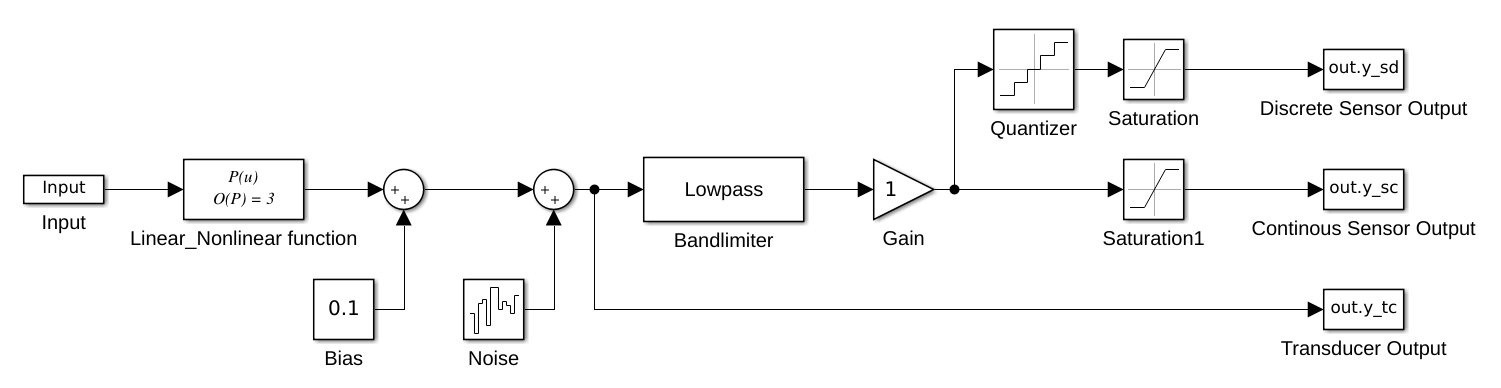

- Figure 2.4 from chapter 2 was obtained by setting: Input(:,2) = mu_x+0.1*sin(2*pi*t*1);

- Saturation in slides is modeled by Input(:,2) = mu_x+1.5*sin(2*pi*t*1);

clear_all_but('SAVE_FLAG');
mu_x=1;
fs=10000;
dur=5*fs; % 5 seconds
t=0:1/fs:dur/fs;
Input(:,1) = t;
Input(:,2) =  mu_x+0.1*sin(2*pi*t*1); % mu_x+1.5*sin(2*pi*t*1);
model_name = 'SimpleSensorModel';
open_system(model_name);
% Linear model
set_param('SimpleSensorModel/Linear_Nonlinear function','Coefs','[1.01,0]') % Bias is shown as a separate block and therefor last element needs to be zero
set_param('SimpleSensorModel/Bias','Value','0.005')
set_param('SimpleSensorModel/Noise','Cov','[0.0000001]')
set_param('SimpleSensorModel/Gain','Gain','2')
out=sim(model_name);

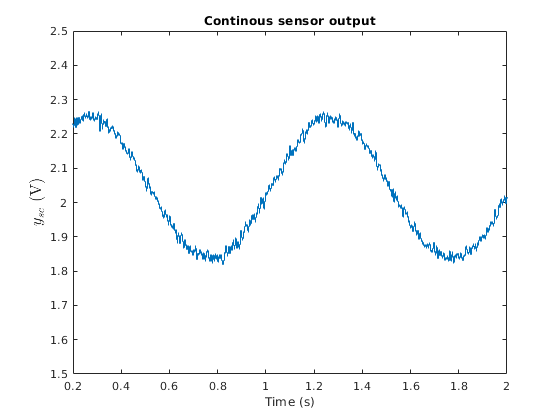

figure, plot(out.y_sc)
xlim([0.2,2])
ylim([1.5,2.5]) %([-0.5,5.5])
title('Continous sensor output')
L=ylabel('$y_{sc}$ (V)', 'FontSize',14);
set(L,'Interpreter','Latex');
xlabel('Time (s)')

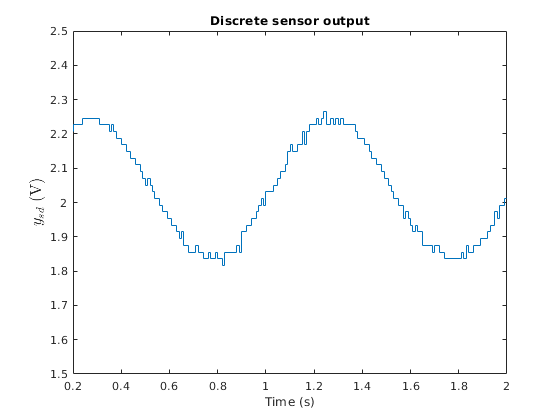

annonation_save('a)',"Fig1.4a.jpg", SAVE_FLAG);

figure, plot(out.y_sd)
xlim([0.2,2])
ylim([1.5,2.5])
title('Discrete sensor output')
L=ylabel('$y_{sd}$ (V)', 'FontSize',14);
set(L,'Interpreter','Latex');
xlabel('Time (s)')

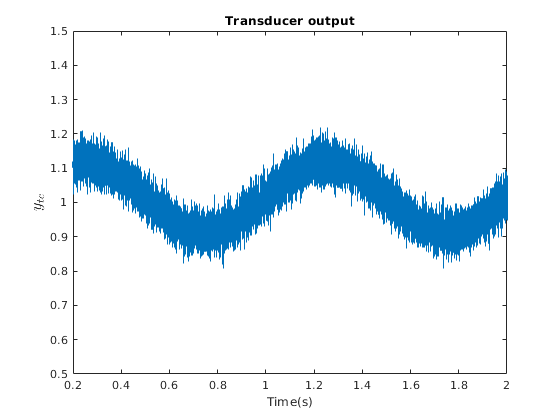

annonation_save('b)',"Fig1.4b.jpg", SAVE_FLAG);
figure, plot(out.y_tc)
xlim([0.2,2])
ylim([0.5,1.5])
title('Transducer output')
L=ylabel('$y_{tc}$', 'FontSize',14);
set(L,'Interpreter','Latex');
xlabel('Time(s)')

## Evaluating nonlinearity

Here, the nonlinear model is introduced first. The model is simulated and the output is obtained from Simulink. Terminal and best fit error are calculated next.

model_name = 'SimpleSensorModel';
open_system(model_name);
Input(:,1) = t;
Input(:,2) = t; % input is modeled as an linear function of t
% NonLinear model
% yt=b1*x+b2*xt.^2+b3*xt.^3; 
b0=0.1; b1=1; b2=0.08; b3=-0.015;
set_param('SimpleSensorModel/Linear_Nonlinear function','Coefs','[-0.015, 0.08,1,0]') % Bias is shown as a separate block and therefor last element needs to be zero
set_param('SimpleSensorModel/Bias','Value','0.1')
set_param('SimpleSensorModel/Noise','Cov','0')
set_param('SimpleSensorModel/Gain','Gain','1')
out=sim(model_name);

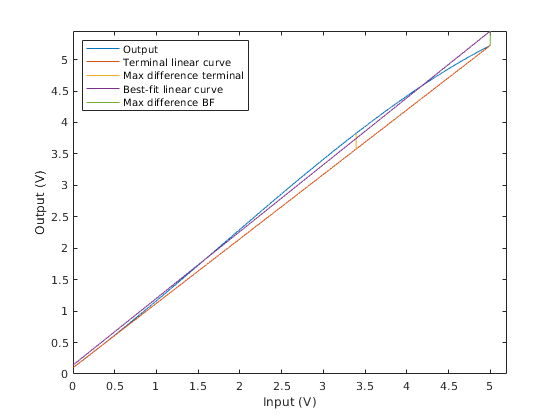

lin_error=PlotNonlinearity(fs, b0, t, Input(:,2), out.y_tc.Data);

annonation_save('',"Fig1.6.jpg", SAVE_FLAG);

fprintf('The terminal non-linearity error is %.1f %%.\n', 100*lin_error(1));

The terminal non-linearity error is 4.8 %.


fprintf('The best fit non-linearity error is %.1f %%.\n', 100*lin_error(2));

The best fit non-linearity error is 4.2 %.


function lin_error=PlotNonlinearity(fs, b0, t, xt, yt)

figure1 = figure;
axes1 = axes('Parent',figure1);
plot(xt, yt);
xlabel("Input (V)")
ylabel("Output (V)")
hold on

%% Terminal fit computation
b1=(yt(end)-yt(1))/(xt(end)-xt(1));
[m,i]=max(abs(yt-(b0 + b1*xt)));
lin_error(1)=m/max(b0 + b1*xt ); %terminal erorr
% Ploting terminal fit
plot(xt,b0 + b1*xt)
plot([xt(i),xt(i)],[b0 + b1*xt(i),yt(i)])

%% Best fit computation
P = polyfit(xt,yt,1);
y_BF = P(1)*xt+P(2); % best fit
[m,i]=max(abs(yt-y_BF));
lin_error(2)=m/max(y_BF); 
% Ploting best fit
plot(xt,y_BF)
plot([xt(i),xt(i)],[y_BF(i),yt(i)])
ylim([0,max(y_BF)])
xlim([0,max(xt)+0.2])
legend("Output", "Terminal linear curve", "Max difference terminal", "Best-fit linear curve", "Max difference BF", 'Location','northwest')


end

## Exersizes

Excersize 1: Modify the gain to 15 of the simulation called Sensor model to generate the output signal that saturates. 

Excersize 2: Modify the resolution of the quantizer from 8 to 16 bits and visualize the output.